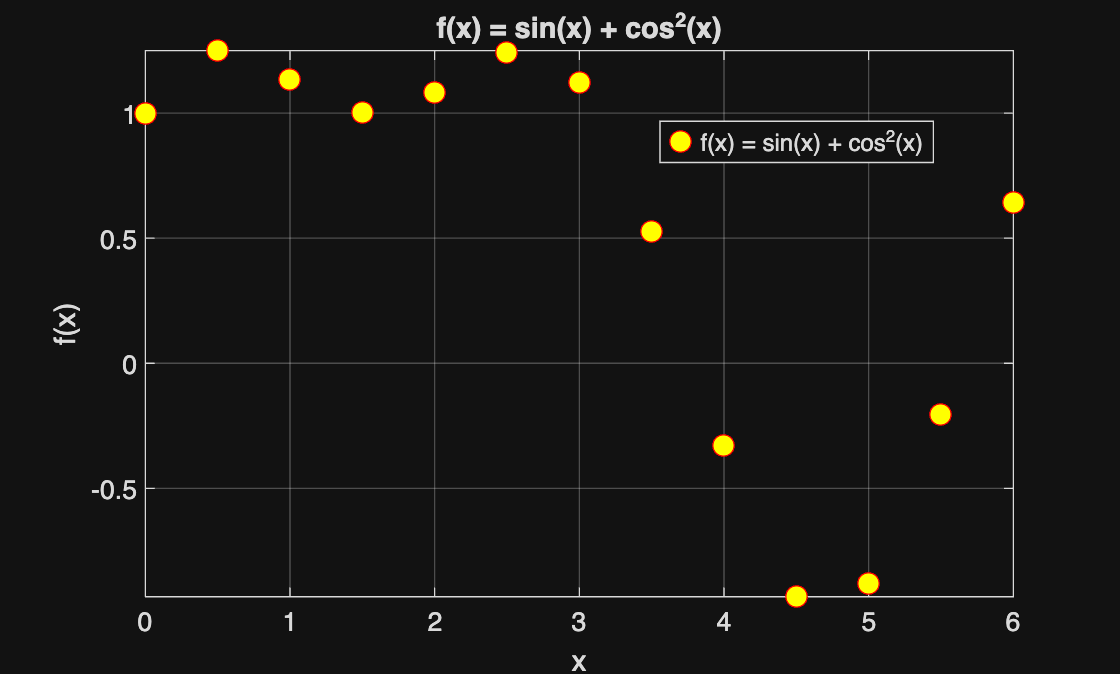

%% 3 LD – Rezultatų grafinis 2D atvaizdavimas (11 variantas)
clear; clc; close all;

%% 1a) f(x) = sin(x) + cos^2(x), x ∈ [0; 2π], žingsnis 0.5
x1 = 0:0.5:2*pi;
f1 = sin(x1) + cos(x1).^2;

figure(1);
plot(x1, f1, 'o', ...
     'MarkerEdgeColor', 'r', ...      % taško kraštas – raudonas
     'MarkerFaceColor', 'y', ...      % taško vidus – geltonas
     'MarkerSize', 8);
title('f(x) = sin(x) + cos^2(x)');
xlabel('x');
ylabel('f(x)');
axis([min(x1) max(x1) min(f1) max(f1)]);
legend('f(x) = sin(x) + cos^2(x)', 'Location', 'best');
grid on;

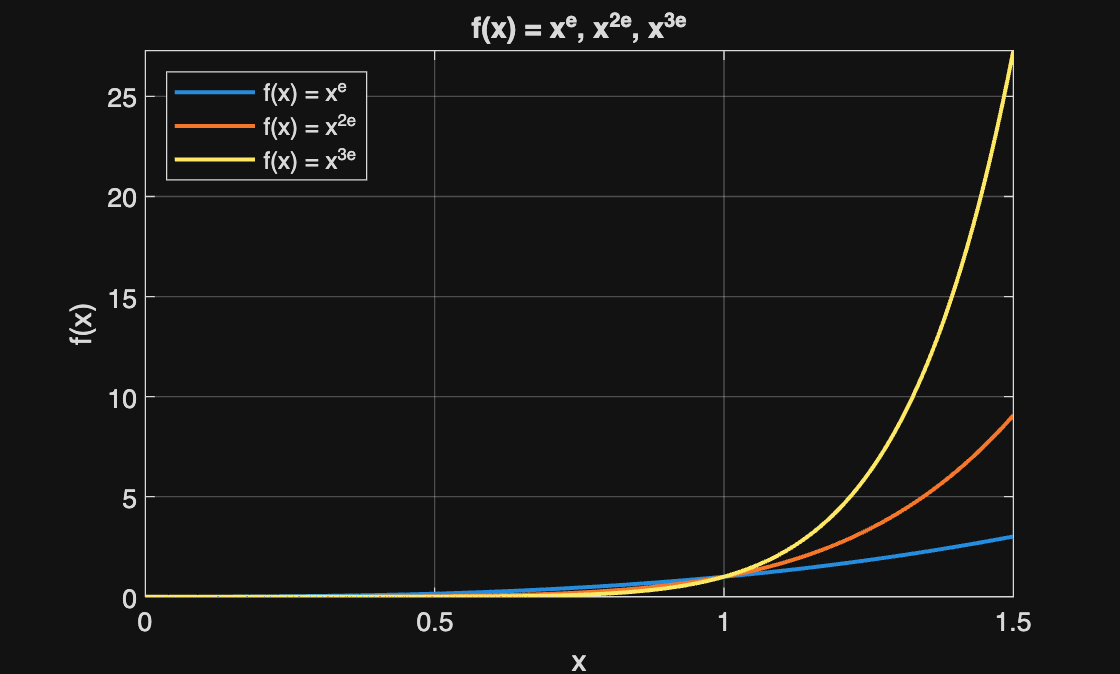


%% 1b) f(x) = x^e, x^{2e}, x^{3e}
x2 = 0:0.01:1.5;    % žingsnis 0.01 – taškas x = 1 patenka tiksliai
F = [x2.^exp(1); x2.^(2*exp(1)); x2.^(3*exp(1))];

figure(2);
plot(x2, F, 'LineWidth', 1.5);
title('f(x) = x^e, x^{2e}, x^{3e}');
xlabel('x');
ylabel('f(x)');
axis([min(x2) max(x2) min(F(:)) max(F(:))]); 
legend('f(x) = x^e', 'f(x) = x^{2e}', 'f(x) = x^{3e}', 'Location', 'northwest');
grid on;


% Bendri taškai: kur visų trijų funkcijų reikšmės sutampa
tol = 1e-10;   % 0.0000000001 – pakankamai mažas, kad nepagautų taškų arti nulio
bendri = abs(F(1,:) - F(2,:)) < tol & abs(F(1,:) - F(3,:)) < tol;
xb = x2(bendri);
disp('x ašies taškai, bendri visoms trims funkcijoms:');

x ašies taškai, bendri visoms trims funkcijoms:


disp(xb);

     0     1



disp('Taškas (0;0) bendras x ir y ašims – visos funkcijos per jį eina.');

Taškas (0;0) bendras x ir y ašims – visos funkcijos per jį eina.


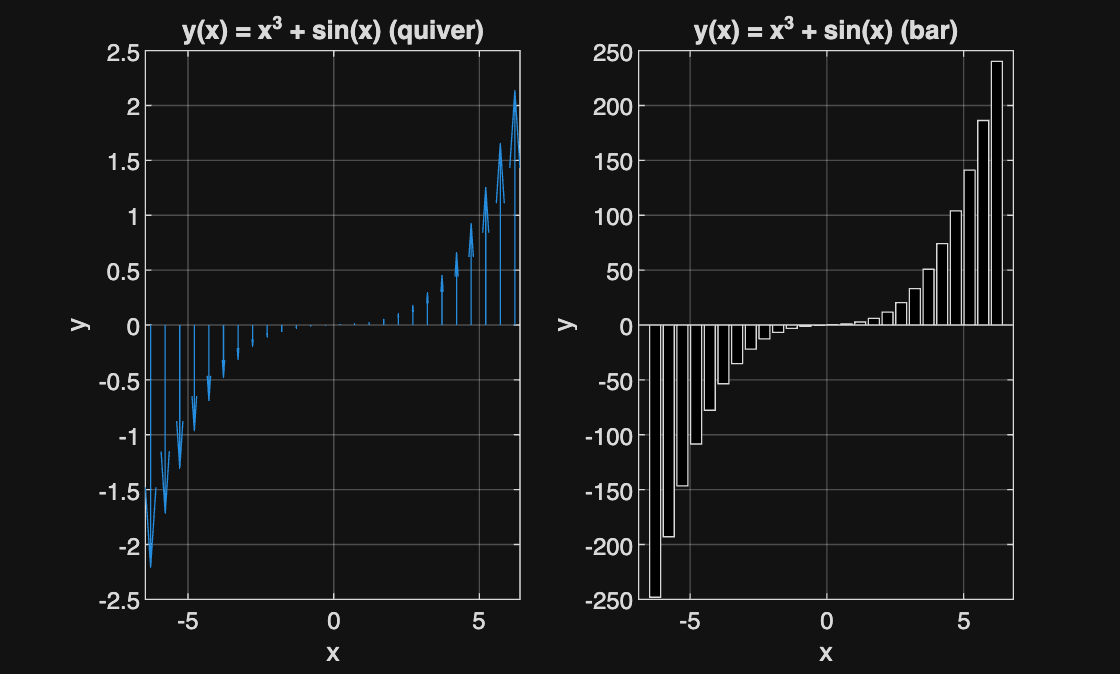


%% 2a) y(x) = x^3 + sin(x) vektoriais horizontalioje linijoje, x ∈ [-2π; 2π]
x3 = -2*pi:0.5:2*pi;
y3 = x3.^3 + sin(x3);

figure(3);
s  % vektoriai iš y=0 su amplitude y(x)
title('y(x) = x^3 + sin(x) (quiver)');
xlabel('x');
ylabel('y');
grid on;

%% 2b) Stulpelinė diagrama
subplot(1, 2, 2);
bar(x3, y3, 'k');
title('y(x) = x^3 + sin(x) (bar)');
xlabel('x');
ylabel('y');
grid on;

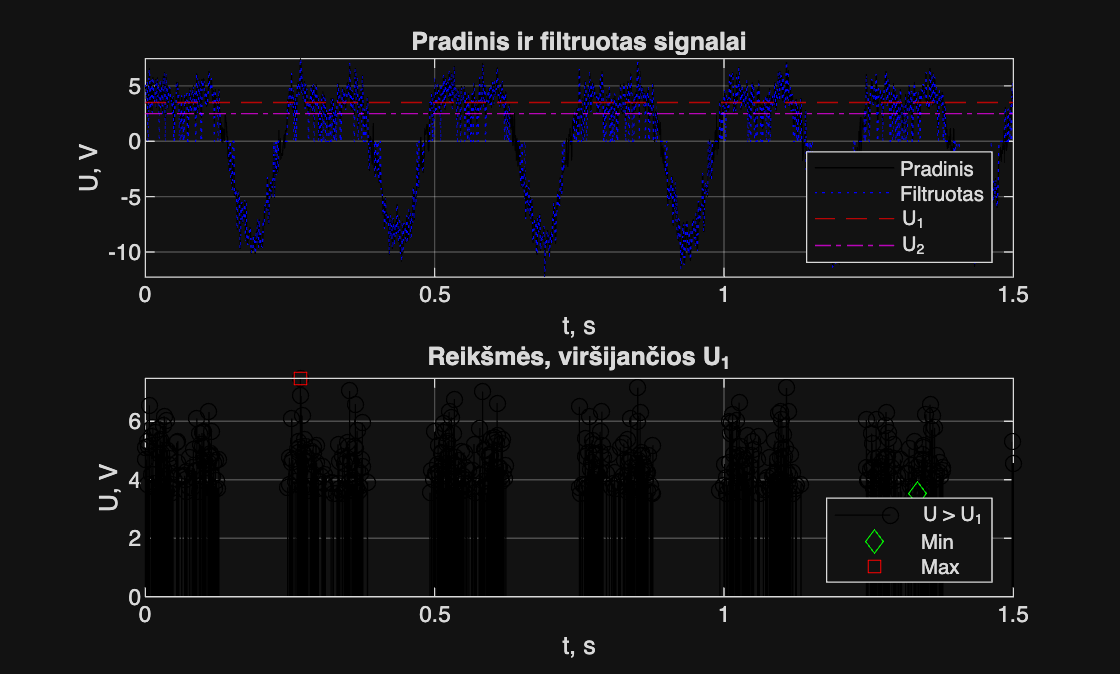



%% 3 LD – Papildoma užduotis (2 variantas)
clear; clc;

%% Signalas iš 2 LD
A = 6; f = 4; sigma = 1.2; U1 = 3.5; U2 = 2.5;

t  = 0:0.001:1.5;
s  = A*sin(2*pi*f*t) + 0.5*A*cos(4*pi*f*t);
sn = s + sigma*randn(size(t));

filtruotas = sn;
filtruotas(abs(filtruotas) < U2) = 0;

%% a) Pradinis ir filtruotas signalai
subplot(2, 1, 1);
plot(t, sn, 'k-', t, filtruotas, 'b:');
yline(U1, 'r--');
yline(U2, 'm-.');
title('Pradinis ir filtruotas signalai');
xlabel('t, s');
ylabel('U, V');
legend('Pradinis', 'Filtruotas', 'U_1', 'U_2', 'Location', 'southeast');
axis([0 max(t) min(sn) max(sn)]);
grid on;

%% b) Reikšmės, viršijančios U1
tv = t(sn > U1);
uv = sn(sn > U1);

subplot(2, 1, 2);
stem(tv, uv, 'k');
hold on;
plot(tv(uv == min(uv)), min(uv), 'gd');
plot(tv(uv == max(uv)), max(uv), 'rs');
hold off;
title('Reikšmės, viršijančios U_1');
xlabel('t, s');
ylabel('U, V');
legend('U > U_1', 'Min', 'Max', 'Location', 'southeast');
axis([0 max(t) 0 max(uv)]);
grid on;